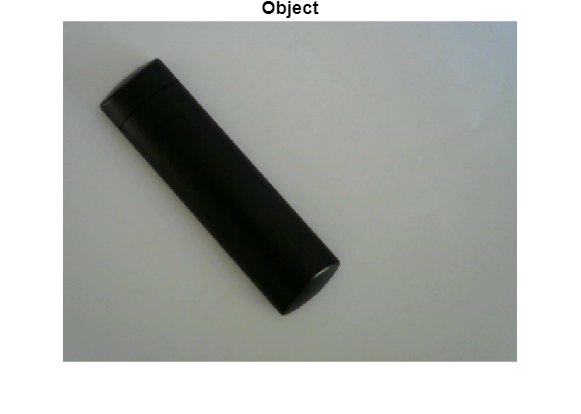

clear all

I = imread("Object.png");
figure, imshow(I)
title('Object');

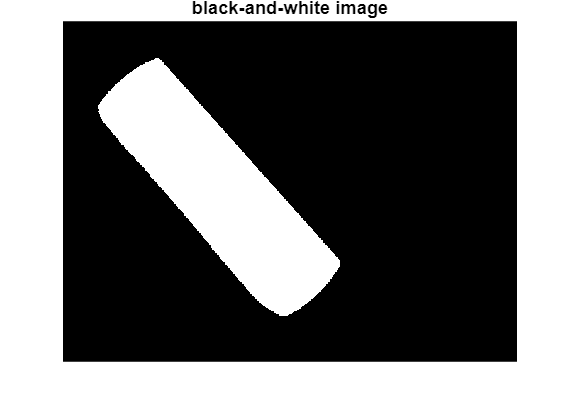


I = rgb2gray(I); % Convert to grayscale
threshold = 125;
bwImage = I < threshold; % Create a binary image
figure, imshow(bwImage), title('black-and-white image')

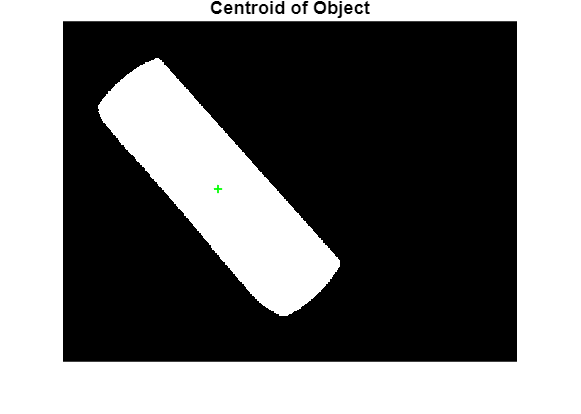


% Initialize moment variables
M10 = 0;
M01 = 0;
M11 = 0;
M20 = 0;
M02 = 0;

% Calculate the zeroth moment (total area of white pixels)
sum_of_pixels = sum(bwImage(:));
M00 = sum_of_pixels;

% Convert the binary image to double for moment calculations
bwImage = double(bwImage);

% Calculate the spatial moments
for i = 1:480
    for j = 1:640
        M10 = M10 + j*(bwImage(i,j));
        M01 = M01 + i*(bwImage(i,j));
        M11 = M11 + i*j*(bwImage(i,j));
        M20 = M20 + j^2*(bwImage(i,j));
        M02 = M02 + i^2*(bwImage(i,j));
    end
end

% Calculate centroid coordinates
X_centroid = M10 / M00;
Y_centroid = M01 / M00;

% Display the image with the centroid marked
figure, imshow(bwImage)
title('Centroid of Object')
hold on
plot(X_centroid, Y_centroid, 'r+', 'MarkerSize', 5, 'LineWidth', 1, 'Color', "g")


% Calculate central moments
mu_00 = M00;
mu_01 = 0;
mu_10 = 0;
mu_11 = M11 - X_centroid * M01;
mu_20 = M20 - X_centroid * M10;
mu_02 = M02 - Y_centroid * M01;

% Create the inertia matrix
J = [mu_20, mu_11; mu_11, mu_02];

% Compute eigenvectors and eigenvalues
[eigenvectors, eigenvalues] = eig(J);
eigenvalues = diag(eigenvalues);

% Find the eigenvector of the max eigenvalue
[~, max_index] = max(eigenvalues);
V = eigenvectors(:, max_index);

% Calculate the major axis (a) and minor axis (b)
a = 2 * sqrt(max(eigenvalues) / M00)

a = 232.0495

b = 2 * sqrt(abs(min(eigenvalues)) / M00)

b = 69.4622

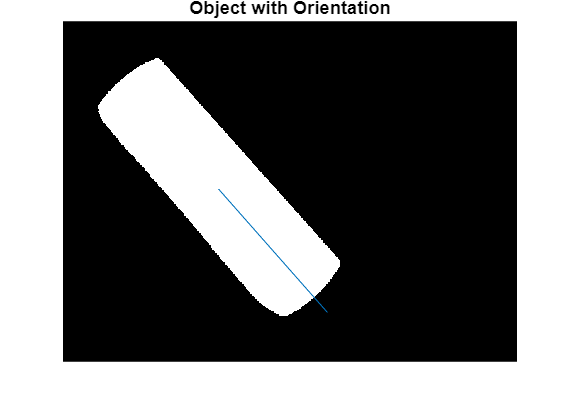


% Calculate the orientation angle of the object (θ)
theta = atan(V(2) / V(1));

% Display the orientation line
L = a;
X2 = X_centroid + L * cos(theta);
Y2 = Y_centroid + L * sin(theta);

figure, imshow(bwImage)
title('Object with Orientation')
hold on
plot([X_centroid X2], [Y_centroid Y2])

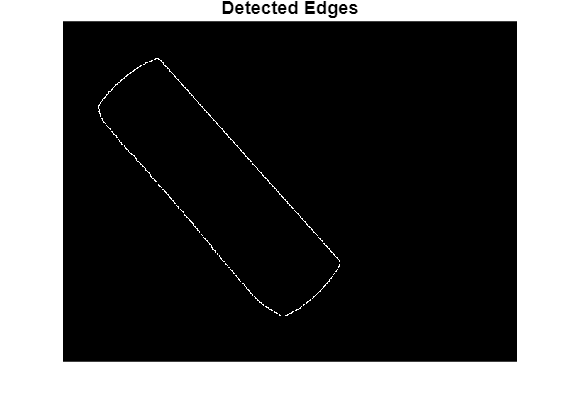


edges = zeros(size(bwImage));
[rows, cols] = size(bwImage);

for i = 2:rows-1
    for j = 2:cols-1
        % Check if there is a change in intensity indicating an edge
        if bwImage(i, j) == 1 && (bwImage(i-1, j) == 0 || bwImage(i+1, j) == 0 || ...
                bwImage(i, j-1) == 0 || bwImage(i, j+1) == 0 || ...
                bwImage(i+1, j+1) == 0 || bwImage(i-1, j-1) == 0 || ...
                bwImage(i-1, j+1) == 0 || bwImage(i+1, j-1) == 0)
            edges(i, j) = 1; % Mark this pixel as an edge
        end
    end
end



figure, imshow(edges), title('Detected Edges');


% Calculate perimeter using the Sobel edge result
p = sum(edges(:)); % Sum of all edge pixels
% Theoretical perimeter using the major and minor axes 
% (2*a=length, 2*b=width)
perimeter = 2*(2*a+2*b)

perimeter = 1.2060e+03


% Calculate the circularity of the object
circularity = (4 * pi * M00) / p^2

circularity = 0.3088

% Circularity using the major and minor axes
theoretical_circularity = (4 * pi * M00) / perimeter^2

theoretical_circularity = 0.4215